# Differential Drive: Kinematic Modeling and Input Modalities

Date: May 1, 2026

**Title:** Comparison of Body-Velocity vs. Wheel-Speed Input Modes

**Description:** This script explores the differentialDriveKinematics class. It demonstrates how MATLAB handles the transition between high-level robot velocities ($v$, $\omega$) and low-level actuator commands ($\omega_L$, $\omega_R$).

**Note on MATLAB Classes:** Each model object (e.g., `differentialDriveKinematics`, `ackermannKinematics`) encapsulates the specific system constraints and provides the `derivative` method to compute $\dot{q}$ (state derivatives) based on chosen `VehicleInputs`.

## Method 1: Body-Level Velocity Control

In this mode, we control the robot using linear velocity $v$ and angular velocity $\omega$. This is ideal for path following and high-level planning.

For a desired radius $R$ and speed $v$, the angular velocity is:


$$\omega = \frac{v}{R}$$


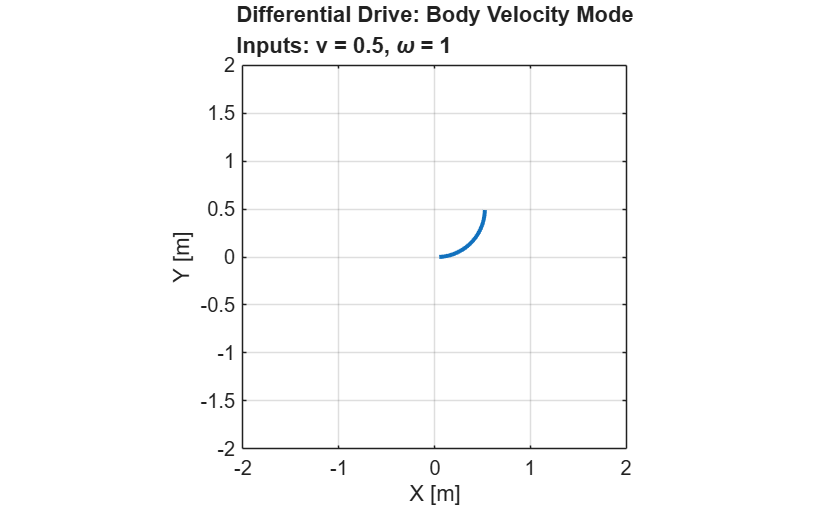

%% Parameters & Model Setup
R = 0.5;                % Desired Radius [m]
v = 0.5;                % Linear Velocity [m/s]
w = v/R;                % Required Angular Velocity [rad/s]
dis = 2*pi*R;           % Full Circle Distance
total_time = dis*0.25/v;% Time for 90-degree turn
dt = 0.1;
t = 0:dt:total_time;

% Instantiate model with Body Velocity inputs
kinematicModel1 = differentialDriveKinematics( ...
    'VehicleInputs', 'VehicleSpeedHeadingRate', ...
    'WheelRadius', 0.04, 'TrackWidth', 0.25);

% Initial State [x, y, theta]
initPose = [0, 0, 0];
pose_cur = initPose';
vel_input = [v, w];
POSE1 = zeros(length(t), 3);

%% Integration Loop
for i = 1:length(t)
    % derivative() uses [v, w] to find [dx, dy, dtheta]
    pose_dot = derivative(kinematicModel1, initPose, vel_input);
    pose_cur = pose_cur + pose_dot * dt;
    POSE1(i,:) = pose_cur'; 
    initPose = pose_cur;
end

% Plotting
figure(1);
plot(POSE1(:, 1), POSE1(:, 2), 'LineWidth', 2)
title({'Differential Drive: Body Velocity Mode', ['Inputs: v = ', num2str(v), ', \omega = ', num2str(w)]})
axis([-2 2 -2 2]); grid on; axis square;
xlabel('X [m]'); ylabel('Y [m]');

## Method 2: Actuator-Level Wheel Speed Control

This mode simulates direct motor control. The inputs are the angular velocities of the left and right wheels ($\omega_L$, $\omega_R$).

The resulting robot motion is governed by:


$$v = \frac{r}{2}(\omega_R + \omega_L), \quad \omega = \frac{r}{L}(\omega_R - \omega_L)$$


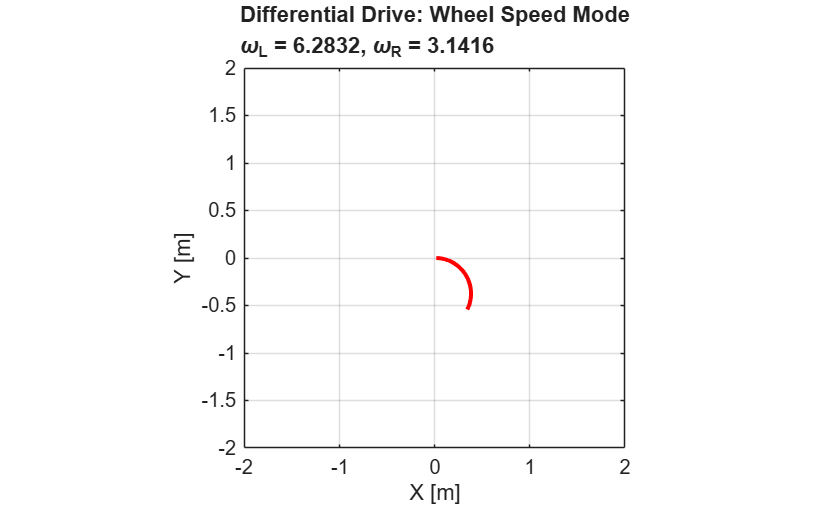

%% Parameters & Model Setup
wL = deg2rad(360); % 360 deg/s Left Wheel
wR = deg2rad(180); % 180 deg/s Right Wheel
omega_input = [wL, wR];
total_time_actuator = 4; % 4 second run
t_act = 0:dt:total_time_actuator;

% Instantiate model with Wheel Speed inputs
kinematicModel2 = differentialDriveKinematics( ...
    'VehicleInputs', 'WheelSpeeds', ...
    'WheelRadius', 0.04, 'TrackWidth', 0.25);

initPose = [0, 0, 0];
pose_cur = initPose';
POSE2 = zeros(length(t_act), 3);

%% Integration Loop
for i = 1:length(t_act)
    % derivative() now expects [wL, wR]
    pose_dot = derivative(kinematicModel2, initPose, omega_input);
    pose_cur = pose_cur + pose_dot * dt;
    POSE2(i,:) = pose_cur'; 
    initPose = pose_cur;
end

% Plotting
figure(2);
plot(POSE2(:, 1), POSE2(:, 2), 'r', 'LineWidth', 2)
title({'Differential Drive: Wheel Speed Mode', ['\omega_L = ', num2str(wL), ', \omega_R = ', num2str(wR)]})
axis([-2 2 -2 2]); grid on; axis square;
xlabel('X [m]'); ylabel('Y [m]');